# Analysis of data from weightsOptimise.py

## Reading the .json file

raw = readdictionary('fullPlayerStats_run1.json');

% Anon function to change keys to floats instead of str
toDouble = @(x) str2double(x);
% Anon sort function handle
sortAsc = @(vec) sort(vec);

refactored = refactorDict(raw, toDouble, 1);
refactored = sortDict(refactored, sortAsc);

## Working on the refactored dictionary

Extracting wins for each player at different weights

% Basic vars for table for subsequent ops
playerList = ["ai_0", "ai_1", "ai_2", "ai_3"];
dims = ["wins", "losses", "tsumos"];
rows = size(playerList,2) * size(dims,2);

stats = zeros(rows, size(keys(refactored), 1));

% loop over each player to fill in the bigass matrix
iter = 1;
for pl = playerList
    
    [wins, losses, tsumos] = extractStats(refactored,pl);

    stats(iter, :) = wins;
    stats(4+iter, :) = losses;
    stats(8+iter, :) = tsumos;

    iter = iter + 1;
end

stats = vertcat(keys(refactored)', stats);

Resulting table generated from above code

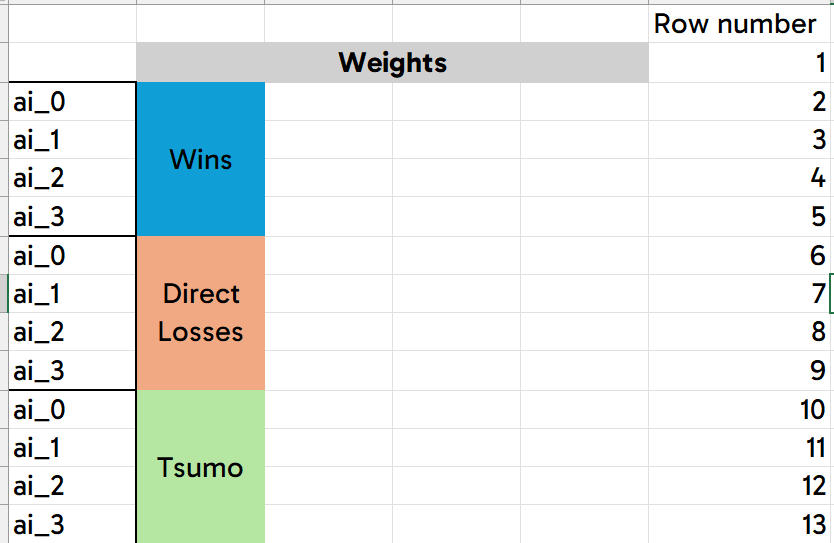

## Plotting!

Wins against weight

weights = keys(refactored)';
% For plotting the fit
weight_fit = linspace(-6, 4, 500);
% Colours
colours = ["#67597a", "#e8ae68", "#a0af84", "#d6a2ad"];

% Start plotting here
format default
for c = 2:5
    scatter(weights, stats(c,:), 20, "x", ...
        MarkerEdgeColor=colours(mod(c, 4)+1), MarkerEdgeAlpha=0.75, ...
        HandleVisibility="off")
    hold on
    % Creating a poly fit line, let's try a quadratic fit!
    fitp = polyfit(weights, stats(c,:), 2);
    disp("ai_" +num2str(c-2) + " best fit:");
    disp(fitp)
    % Plot the fit
    name = strcat(playerList(c-1), ' + Fit');
    plot(weight_fit, polyval(fitp, weight_fit), '-', LineWidth=1.5, Color=colours(mod(c,4)+1), ...
        DisplayName=name)
end

ai_0 best fit:


   1.0e+03 *

    0.0078    0.0466    2.9260



ai_1 best fit:


   1.0e+03 *

   -0.0268   -0.1078    3.7086



ai_2 best fit:


   1.0e+03 *

    0.0109    0.0732    3.0244



ai_3 best fit:


   1.0e+03 *

    0.0070    0.0379    2.9334



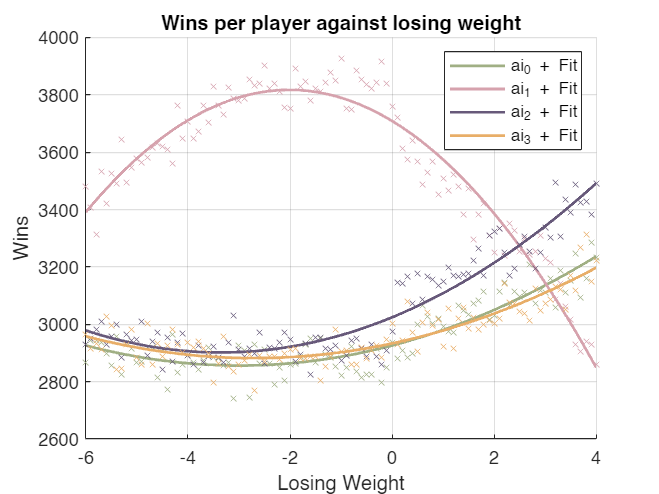

grid on
legend()
xlabel('Losing Weight')
ylabel('Wins')
title('Wins per player against losing weight')
hold off

Losses against weight

% Start plotting here
figure
hold on
for a = 6:9
    scatter(weights, stats(a,:), 20, "x", ...
        MarkerEdgeColor=colours(mod(a, 4)+1), MarkerEdgeAlpha=0.75, ...
        HandleVisibility="off");
    % Fit curve
    if (a == 7)
        % Logistic regression
        fitp = polyfit(weights, stats(a,:), 3);
    else
        % Curve fitting function
        fitp = polyfit(weights, stats(a,:), 2);
    end
    % Display the fit
    disp("ai_" +num2str(a-6) + " best fit:");
    disp(fitp)
    % Plot the fit
    name = strcat(playerList(a-5), ' + Fit');
    plot(weight_fit, polyval(fitp, weight_fit), '-', LineWidth=1.5, Color=colours(mod(a,4)+1), ...
    DisplayName=name)
end

ai_0 best fit:


   1.0e+03 *

   -0.0042   -0.0358    3.1161



ai_1 best fit:


   1.0e+03 *

   -0.0007    0.0129    0.1915    3.2072



ai_2 best fit:


   1.0e+03 *

   -0.0069   -0.0587    3.1337



ai_3 best fit:


   1.0e+03 *

   -0.0051   -0.0379    3.1461



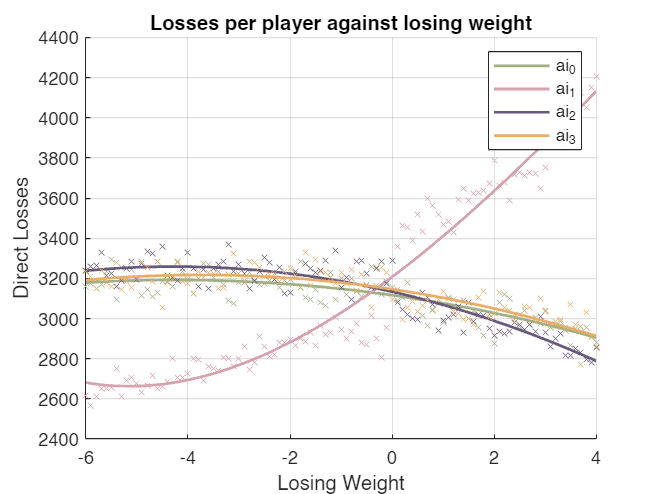

grid on
legend(playerList)
xlabel('Losing Weight')
ylabel('Direct Losses')
title('Losses per player against losing weight')
hold off

Tsumo against weight

% Start plotting here
figure
hold on
for b = 10:13
    scatter(weights, stats(b,:), 20, "x", ...
        MarkerEdgeColor=colours(mod(b, 4)+1), MarkerEdgeAlpha=0.75, ...
        HandleVisibility="off");
    
    % Quadratic fit
    fitp = polyfit(weights, stats(b, :), 2);
    % Display the fit
    disp("ai_" +num2str(b-10) + " best fit:");
    disp(fitp)

    name = strcat(playerList(b-9), ' + Fit');
    plot(weight_fit, polyval(fitp, weight_fit), '-', LineWidth=1.5, ...
        Color=colours(mod(b,4)+1), DisplayName=name);
end

ai_0 best fit:


    1.9617   -6.9100  818.7905



ai_1 best fit:


   1.0e+03 *

   -0.0083   -0.0345    1.1076



ai_2 best fit:


    1.7793   -2.6423  865.3353



ai_3 best fit:


    0.7099  -10.5377  840.0346



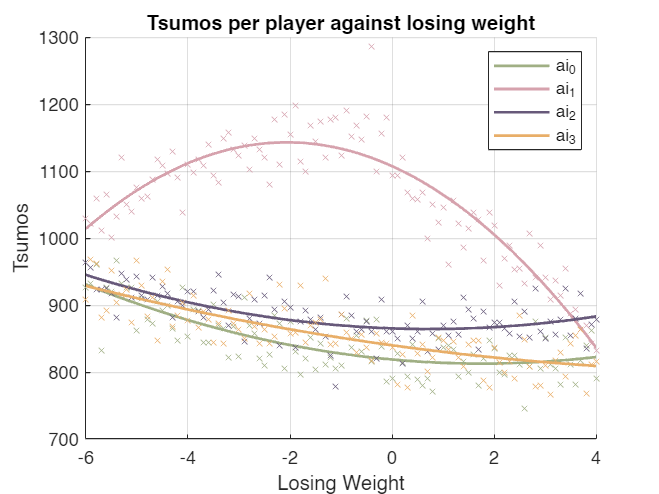

grid on
legend(playerList)
xlabel('Losing Weight')
ylabel('Tsumos')
title('Tsumos per player against losing weight')
hold off

### Deriving the winning ratio W/L Ratio

% Gather the amount of times some sumoed.
allTsumos = stats(10,:);
for p_index = 1:3
    allTsumos = allTsumos + stats(10+p_index, :);
end
% Wins = 3 * Tsumos + Wins
% losses = all Tusmos - MyOnes + Losses
RatioStats = zeros(4, size(stats,2));
% loop over all of the players to create the ratio table
for p_index = 1:size(playerList,2)
    playerWins = 3 * stats(9 + p_index, :) + stats(1 + p_index, :);
    playerLosses = allTsumos - stats(9+p_index, :) + stats(5 + p_index, :);
    
    RatioStats(p_index,:) = playerWins./playerLosses; % = W/L ratio
end

Plotting the W/L Ratio

figure
hold on
for p_index = 1:size(playerList,2)
    name = playerList(p_index);
    scatter(weights, RatioStats(p_index, :), ".",MarkerEdgeColor=colours(p_index), ...
        LineWidth=1.5, HandleVisibility="off");

    % Fitting
    fitp = polyfit(weights, RatioStats(p_index,:), 2);
    % Display the fit
    disp("ai_" +num2str(p_index-1) + " best fit:");
    disp(fitp)
    % plot the fit
    plot(weight_fit, polyval(fitp, weight_fit), '-', LineWidth=1.5, ...
        Color=colours(p_index), DisplayName=name);
end

ai_0 best fit:


    0.0040    0.0181    0.9088



ai_1 best fit:


   -0.0122   -0.0660    1.2361



ai_2 best fit:


    0.0051    0.0307    0.9547



ai_3 best fit:


    0.0032    0.0145    0.9192



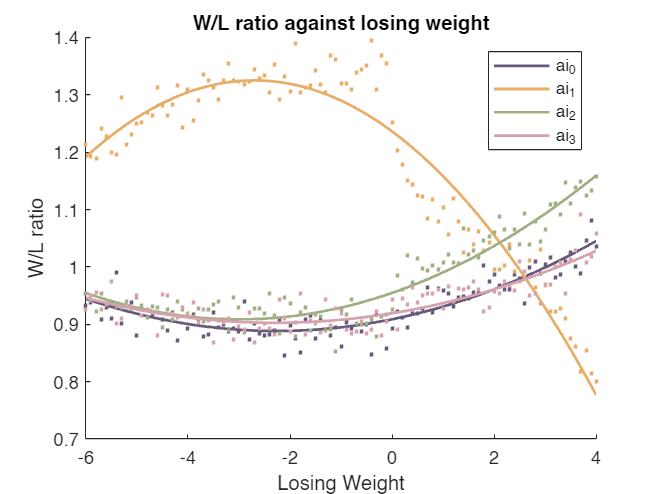

legend()
title('W/L ratio against losing weight')
xlabel('Losing Weight')
ylabel('W/L ratio')
hold off

function refactoredDc = refactorDict(oldDict, operation, fromIndex)
    key_arr = keys(oldDict);
    numKeys = size(key_arr);
    numKeys = numKeys(1);

    if fromIndex <= numKeys
        refactoredDc = refactorDict(oldDict, operation, fromIndex+1);
        key = key_arr(fromIndex);
        value = oldDict(key);
        refactoredDc = insert(refactoredDc, operation(key), value);
        return
    end
    
    refactoredDc = dictionary;
    return
end

function sortedDc = sortDict(dict, sortFunction)
    % Sorts a dictionary by processing its keys with a
    % given sortfunction
    sortedDc = dictionary;
    sortedKeys = sortFunction(keys(dict));

    % Reassigns the key value pairs after sorting
    for k = sortedKeys
        sortedDc(k) = dict(k);
    end
    return
end

function [wins, loss, tsumo] = extractSubDicts(dict, weight)
    % Gets the win loss tsumo tags from the sub dictionary
    % of each weight
    weightDict = dict(weight);
    weightDict = weightDict{1,1};
    
    winsCell = weightDict("win");
    wins = winsCell{1,1};
    
    lossCell = weightDict("loss");
    loss = lossCell{1,1};
    
    tsumoCell = weightDict("tsumo");
    tsumo = tsumoCell{1,1};
return
end

function [playerWins, playerLosses, playerTsumos] = extractStats(dict,player)
    % Priming the output lists
    weightsKeys = keys(dict);
    playerWins = zeros(size(weightsKeys));
    playerLosses = repmat(playerWins, 1);
    playerTsumos = repmat(playerWins, 1);
    
    % Loop over all the weights and add the wins losses tsumos
    % to each respective list
    for w = 1:size(weightsKeys,1)
        [wins, losses, tsumos] = extractSubDicts(dict, weightsKeys(w));
        playerWins(w) = wins(player);
        playerLosses(w) = losses(player);
        playerTsumos(w) = tsumos(player);
    end
end